# Comparing Antenna Panel Calculations with NeoRadium

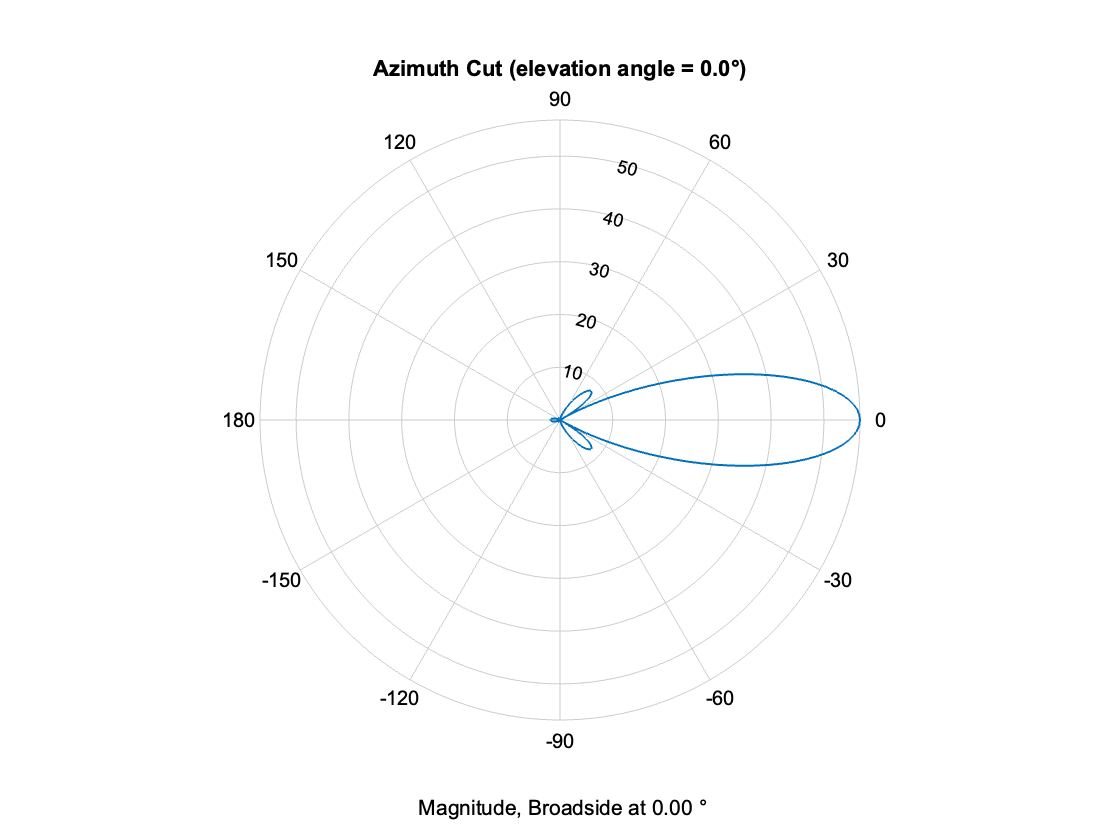

c = physconst('LightSpeed');
fc = 6e9;
lambda = c/fc;
antenna3 = phased.NRAntennaElement('PolarizationAngle', 0);
antenna4 = phased.NRAntennaElement('PolarizationAngle', 90);

array = phased.NRRectangularPanelArray('ElementSet', ...
        {antenna3, antenna4},'Size',[4, 4, 1, 1],'Spacing', ...
        [0.5*lambda, 0.5*lambda,3*lambda, 3*lambda]);
pattern(array,fc,-180:180,0,'CoordinateSystem','polar','type', 'efield', 'Normalize', false);

a = pattern(array,fc,-180:180,0,'CoordinateSystem','polar','type', 'efield', 'Normalize', false);
a(176:185)

ans =    53.7669
   54.8577
   55.7174
   56.3376
   56.7122
   56.8375
   56.7122
   56.3376
   55.7174
   54.8577


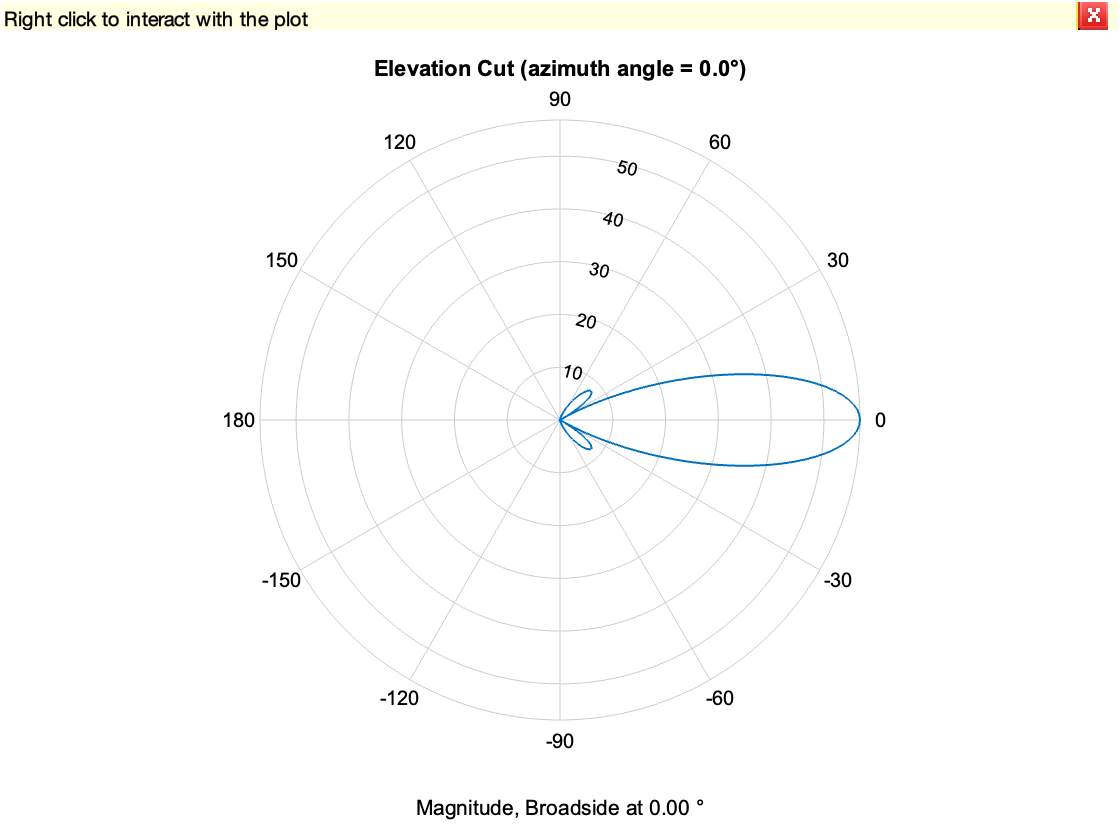

pattern(array,fc,0,-90:90,'CoordinateSystem','polar','type', 'efield', 'Normalize', false);

a = pattern(array,fc,0,-90:90,'CoordinateSystem','polar','type', 'efield', 'Normalize', false);
a(131:140)

ans =     7.7733
    7.9447
    8.0336
    8.0479
    7.9953
    7.8835
    7.7200
    7.5120
    7.2665
    6.9901


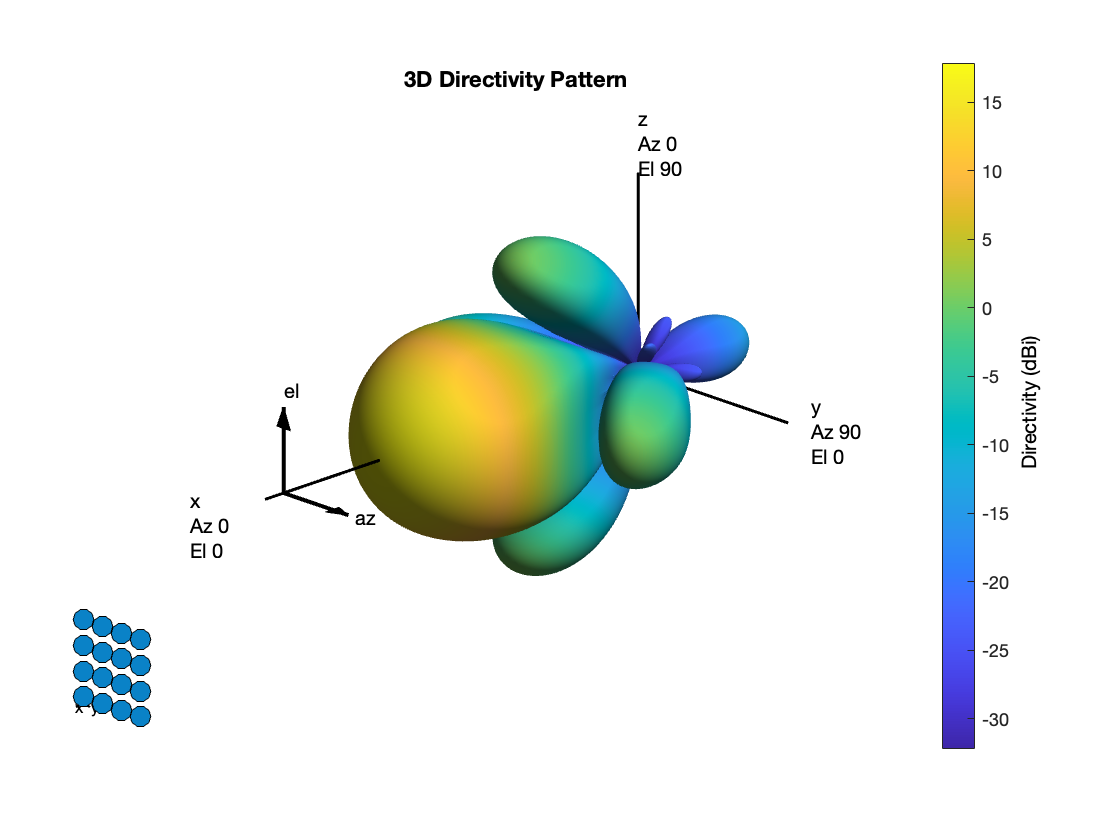


tic;
pattern(array,fc,'ShowArray',true);

toc;

Elapsed time is 114.807911 seconds.


% Saving files 
outPath = fileparts(matlab.desktop.editor.getActiveFilename);

directivity = pattern(array,fc,'ShowArray',true);
save(strcat(outPath,'/PanelDirectivity.mat'),'directivity');

powerDb = pattern(array,fc,'ShowArray',true, 'type', 'powerdb', 'Normalize', false);
save(strcat(outPath,'/PanelPowerDb.mat'),'powerDb');

field = pattern(array,fc,'ShowArray',true, 'type', 'efield', 'Normalize', false);
save(strcat(outPath,'/PanelField.mat'),'field');

directivity(86:95,181)

ans =    17.3855
   17.5599
   17.6950
   17.7912
   17.8487
   17.8679
   17.8487
   17.7912
   17.6950
   17.5599
